%Test Zone

ans = 1×8 cell array
    {'P1'}    {'3'}    {'T1'}    {'4'}    {'6'}    {'T6'}    {'8'}    {0×0 char}


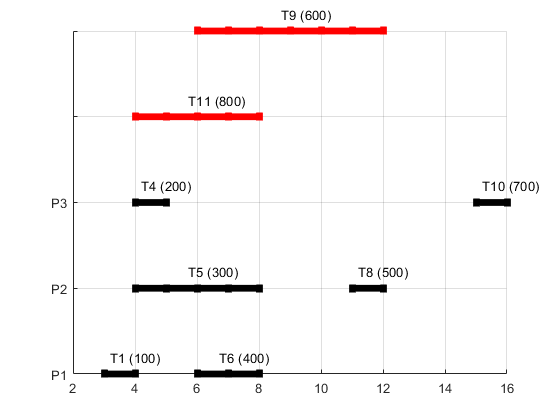

clear all
str = convertStringsToChars(splitlines(extractFileText('Test.txt')));
profits = str2double(splitlines(extractFileText('Profit.txt')));
progs={};
prog={};
tasks={};
for p=1:(length(str)-1)
    if(str{p}(1)=='P')
        progs{p} = split(str(p));
        final = p;
    else
        tasks{(p-(final))}=split(str(p));
    end
end
figure(1)

%prints
close all
hold on
for  i= 1:final
    for k=3:3:(length(progs{i})-1)
        t=(str2double(progs{i}{k-1}):str2double(progs{i}{k+1}));
        p=ones(1,length(t));
        avg = (t(1)+(t(end)-t(1))/2)-0.3;
        title = progs{i}{k};
        fim = length(regexp(title,'[0-9]'))+1;
        iprofit = str2num(title(2:fim));
        if(profits(iprofit)~=1)
            txt = [progs{i}{k},' (',int2str(profits(iprofit)),')'];
        else
            txt = title;
        end
        text(avg,(i+0.2),txt);
        prog{i} = char(progs{i}(1));
        plot(t, i*p, 'k-|',"LineWidth",5);
    end   
end
for q=1:length(tasks)
    t=(str2double(tasks{q}{1}):str2double(tasks{q}{3}));
    p=ones(1,length(t));
    avg =(t(1)+(t(end)-t(1))/2)-0.3;
    title = tasks{q}{2};
    fim = length(regexp(title,'[0-9]'))+1;
    iprofit = str2num(title(2:fim));
    if(profits(iprofit)~=1)
        txt = [tasks{q}{2},' (',int2str(profits(iprofit)),')'];
    else
        txt = title;
    end
    text(avg,((q+final)+0.2),txt);
    plot(t, (q+final)*p, 'r-|',"LineWidth",5);
    prog{q+final} = char('');
end
hold off
grid;
ay = gca;
ay.YTickLabel = prog;
yticks(1:length(prog));